# Survey on controllers

## Simulation parameters

clear all
% Simulation time (ms)
T = 2000;
% Simulation step (ms)
dt  = 1;
idt = 1;

qi  = [0; 0]; % Initial joint state
dqi = [0; 0]; % Initial joint velocity
ddqi= [0; 0]; % Initial joint acceleration
ui  = [0; 0]; % Initial torque input
% Final conditions
qd  = [pi/2; -pi/2]; % Final joint state
dqd = [0; 0]; % Final joint velo city
ddqd= [0; 0]; % Final joint acceleration

% Robot variables
q  = qi;   % Joint state (variable)
dq = dqi;  % Joint velocity
ddq= ddqi; % Joint Acceleration
u  = ui;   % Torque input

## 2R Parameters

m = [15; 20];
l = [5; 4];
d = [3; 5];
g0 = 0.00981;

N = diag([100, 100]);% Reduction Ratio
D = diag([0.8, 0.8]); % Viscous Friction Matrix
J = diag([1., 1.]);   % Inertia Matrix

dqconstr = [
    -1.01, 1.01;
    -1.01, 1.01
    ];
qconstr  = [
    deg2rad(-180), deg2rad(180);
    deg2rad(-360), deg2rad(360)
    ];

nr = 0.01; % Nominal-Real additive factor for real parameters
[a, m] = eval_2r_params(l, d, m, g0);
[ar, mr] = eval_2r_params_real(l, d, m, g0, nr);
% By slightly varying base parameters (mass, link length and CoM offset)
% different coefficients are obtained
a, ar

a = 	1.0e+03 *

    1.1350
    0.5000
    0.5000
    0.0013
    0.0008


ar = 	1.0e+03 *

    1.1311
    0.4975
    0.4975
    0.0013
    0.0008


%% PD-Controller Parameters
kp = 1  * eye(2);
kd = 1 * eye(2);
err= qd - q;
err_prec = err;

### Simulation Phase

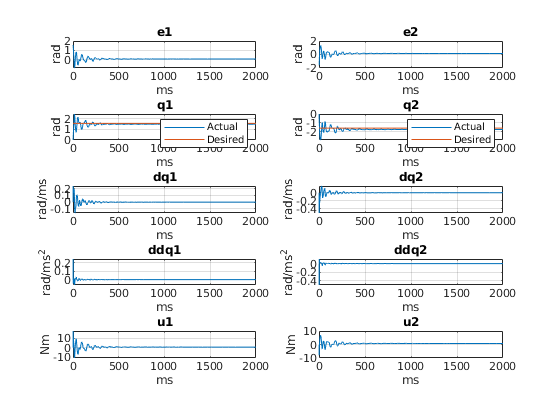

num_steps = floor(T / dt);
data_mat(1:12, num_steps) = 0.0;
for i = 1:dt:T
    % Update plot
    data_mat = data_store(data_mat, i, q, dq, ddq, err, u, qd);
    err = double(qd - q);
    % Compute u
    u = controller_decentralized(q, dq, ddq, a, D, N, kp, kd, err, err_prec);
    %u = controller_decentralized_ext(q, dq, ddq, a, D, N, kp, kd, err, err_prec);
    %u = controller_centralized_fbl(q, dq, ddq, a, D, N, kp, kd, err, err_prec);
    [q, dq, ddq] = step_2r_model(dt, q, dq, u, ar, D, qconstr, dqconstr);
    err_prec = err;
end
labels = [["ms", "rad"]; ["ms", "rad"]; ["ms", "rad"]; ["ms", "rad"]; ["ms", "rad/ms"]; ["ms", "rad/ms"]; ["ms", "rad/ms^2"]; ["ms", "rad/ms^2"]; ["ms", "Nm"]; ["ms", "Nm"]];
titles = ["e1"; "e2"; "q1"; "q2"; "dq1"; "dq2"; "ddq1"; "ddq2"; "u1"; "u2"];
data_plot(data_mat, labels, 5, 2, titles);